## Exercise 3: Multivariable Systems

### 3.1 Poles, zeros and RGA

#### Ex 3.1.1

sysmp = nonminphase;
[num, den] = tfdata(sysmp);
G = tf(num,den)

G =
 
  From input 1 to output...
         0.02088
   1:  -----------
       s + 0.05106
 
               0.003163
   2:  -------------------------
       s^2 + 0.1378 s + 0.004265
 
  From input 2 to output...
               0.002586
   1:  -------------------------
       s^2 + 0.1369 s + 0.004382
 
         0.01808
   2:  -----------
       s + 0.04692
 
Continuous-time transfer function.



pole(G(1,1))

ans = -0.0511

tzero(G(1,1))


ans =

  0×1 empty double column vector




pole(G(1,2))

ans =    -0.0858
   -0.0511


tzero(G(1,2))


ans =

  0×1 empty double column vector




pole(G(2,1))

ans =    -0.0909
   -0.0469


tzero(G(2,1))


ans =

  0×1 empty double column vector




pole(G(2,2))

ans = -0.0469

tzero(G(2,2))


ans =

  0×1 empty double column vector



#### Exercise 3.1.2

pole(G)

ans =    -0.0511
   -0.0909
   -0.0469
   -0.0858
   -0.0511
   -0.0469


tzero(G)

ans =    -0.2356
    0.0589
   -0.0511
   -0.0469


No LHP poles or zeros -> no constraints

#### Exercise 3.1.3

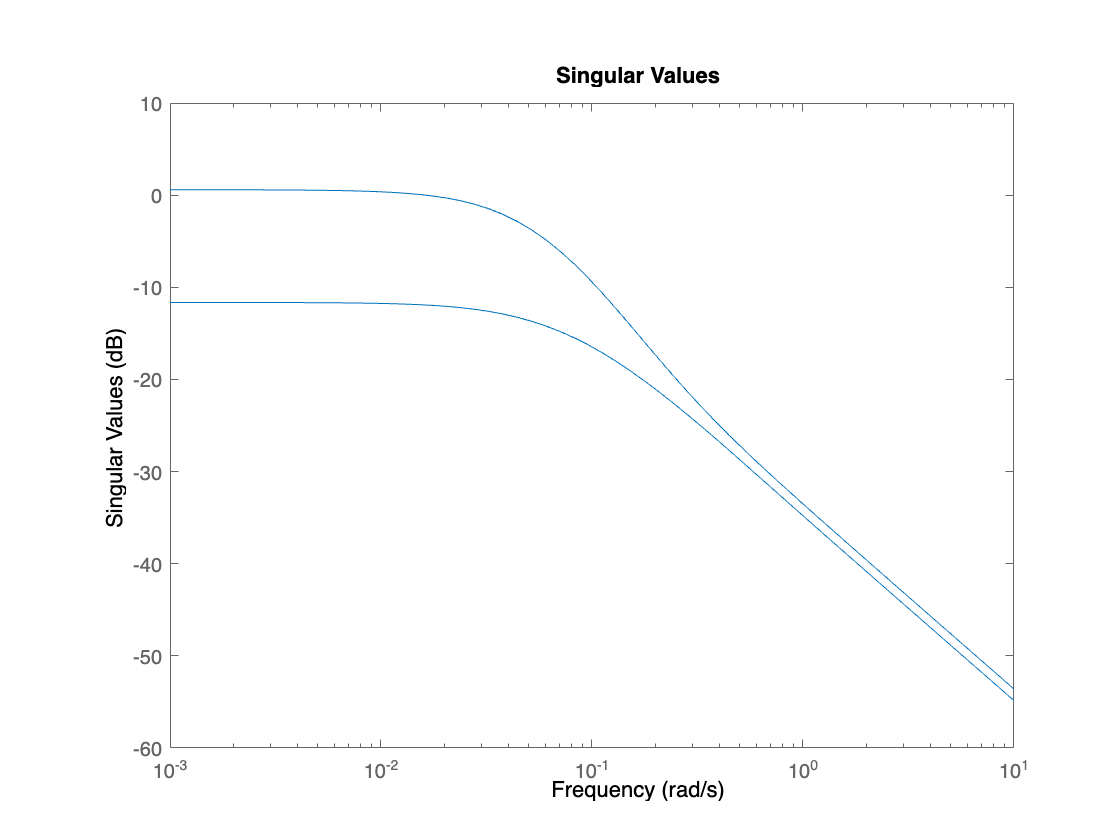

sigma(G)

hinfnorm(G)

ans = 1.0702

#### Exercise 3.1.4

G_0 = dcgain(G);
inv_G = pinv(G_0);
tr_G = transpose(inv_G);
 
rga_G = G_0.*tr_G

rga_G =    -0.5625    1.5625
    1.5625   -0.5625


#### Exercise 3.1.5

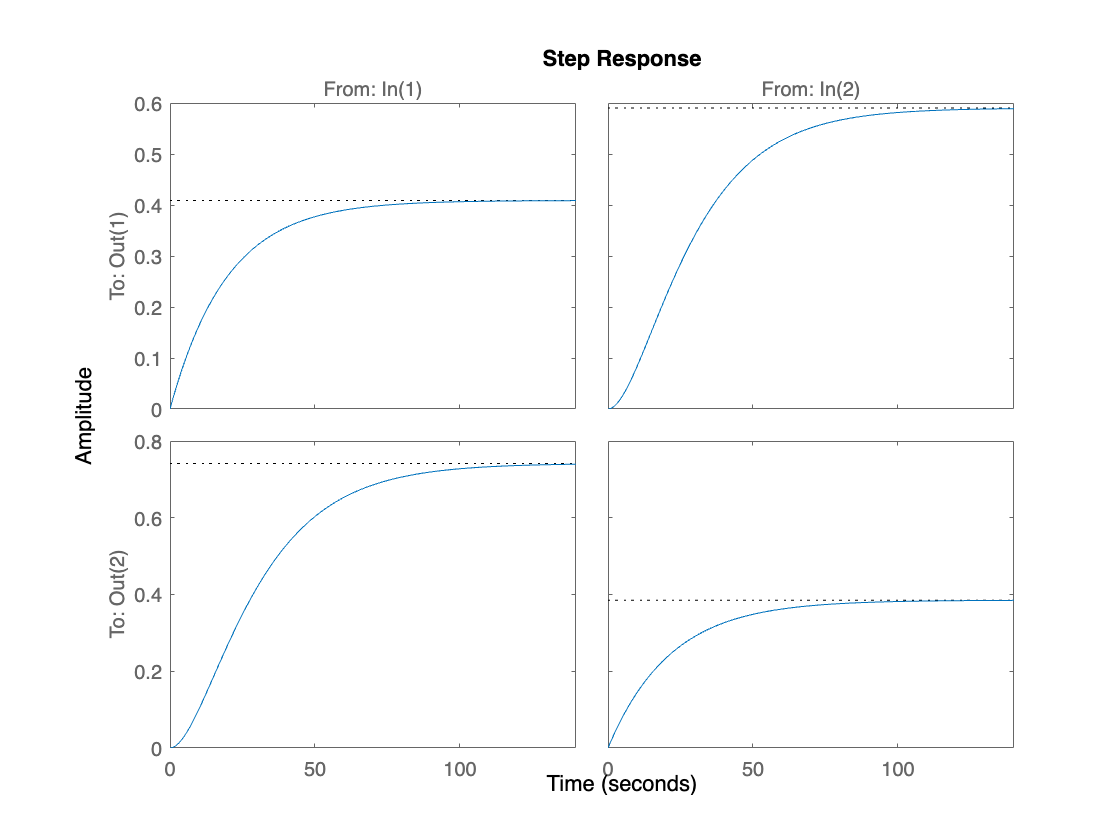

step(G)